***Wireless Communications EL-GY 6023***

Homework 7 - Tommy Azzino (ta1731)

Problem 2

(b)

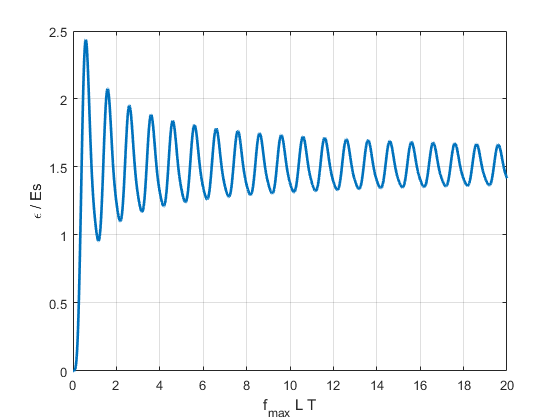

npoints = 10000;
fmax_L_T = linspace(0,20,npoints);
mse = 1.5*besselj(0, zeros(1, length(fmax_L_T))) + ...
    0.5*real(besselj(0, fmax_L_T*4*pi)) - 2*real(besselj(0, fmax_L_T*2*pi));
 
figure;
plot(fmax_L_T, mse, "LineWidth", 2);
grid on; xlabel('f_{max} L T'); ylabel('\epsilon / Es');

(c )

% one reference symbol every 2L samples
fmax = 100;
T = 1e-6;
epsilon_over_Es = 1/db2pow(20);

fmax_L_T_target = fmax_L_T(mse < epsilon_over_Es);
L = fmax_L_T_target(end)/(fmax*T);
min_overhead = 1/(2*L);
fprintf(1, 'The minimum overhead is: %f\n', min_overhead);

The minimum overhead is: 0.000543
